# Identificazione di parametri dell'equazione dinamica

Nei sistemi meccanici è spesso possibile scrivere l'equazione della dinamica dai bilanci di forze.

Nel caso più semplice di un singolo azionamento e sistema rigido, spesso la dinamica diventa:


$$J \dot{\omega} = \tau - C_v \omega - C_c sign(\omega)$$


dove compaiono:

-  l'inerzia del sistema $J$

- la coppia applicata dal motore $\tau$

- l'attrito viscoso $C_v\omega$, qui considerato lineare con la velocità

- l'attrico Coloumbiano $C_c sign(\omega)$

Si può vedere come l'equazione è lineare nei parametri. Grazie a ciò è possibile stimare attraverso i minimi quadrati.

**Nota**: la funzione segno è sensibile al rumore quando la velocità è pressochè nulla. Possibili soluzioni: scartare i dati con velocità quasi nulla, o raccordare il segno approssimandolo con $sign(x)=\tanh(kx)$, con $k$ abbastanza grande

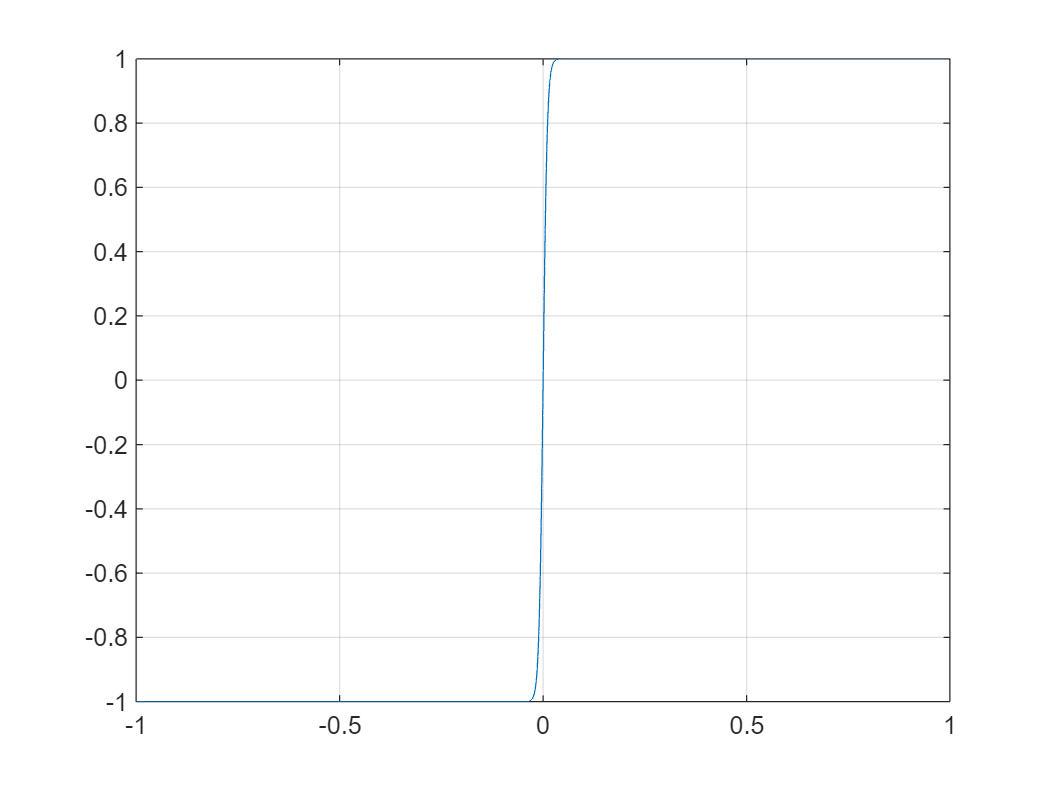

figure
x=linspace(-1,1,1e4)';
plot(x,tanh(100*x))
grid on

**Nota 2**: quando la velocità è nulla, tutti i valori $-C_c <\tau<C_c$ mantengono il sistema fermo.

## Identificazione

Riscrivendo l'equazione


$$J \dot{\omega} = \tau - C_v \omega - C_c sign(\omega)$$


in


$$\tau = J \dot{\omega} + C_v \omega + C_c sign(\omega)$$


e raccogliendo


$$\tau=\left[\begin{array}{ccc}\dot{\omega} & \omega & sign(\omega) \end{array}\right ]\;\cdot\;\left[\begin{array}{c}J\\C_v\\C_c\end{array}\right]$$


dove

$\left[\begin{array}{ccc}\dot{\omega} & \omega & sign(\omega) \end{array}\right ]$ è il regressore dell'equazione della dinamica

load identificazione_parametri_fisici.mat

regressore=[Domega omega tanh(1000*omega)];

i paramtri si possono calcolare con i minimi quadrati

parametri=regressore\tau

parametri =     0.0100
    0.1871
    4.0202


calcolo la coppia da modello e la confronto

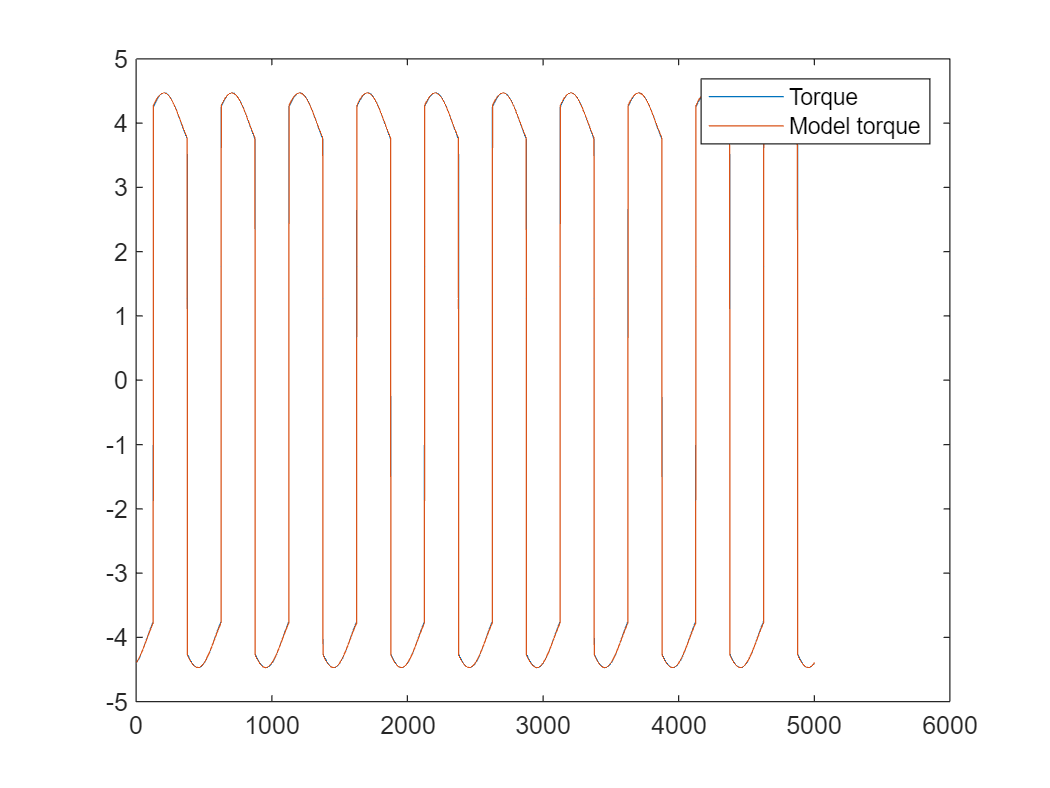

tau_model=regressore*parametri;
figure
plot([tau,tau_model])
legend('Torque','Model torque')

## Esempio di sistemi soggetti a gravità

In caso si sistemi soggetti alla gravità (pensiamo ad un pendolo), c'è un contributo dovuto alla forza di gravtià moltiplicata per il braccio. Considerando il caso generico in cui il baricentro non è allineato con gli assi x e y quando l'angolo è 0, abbiamo due contributi (contenti massa e distanza del baricentro) dipendenti da seno e coseno.


$$J \dot{\omega} = \tau - C_v \omega - C_c sign(\omega) - C_{g1}\sin(\alpha) - C_{g2}\cos(\alpha),\;\;\dot{\alpha}=\omega$$


anche qui è possibile scrivere il regressore e usare i minimi quadrati

## Sistemi con più giunti

Per sistemi rigidi, è sempre possibile scrivere il regressore e usare i minimi quadrati, anche se non tutti i parametri sono stimabili.

[https://iris.unibs.it/bitstream/11379/555157/2/RP_PhD_thesis_pdfA.pdf](https://iris.unibs.it/bitstream/11379/555157/2/RP_PhD_thesis_pdfA.pdf)

Consideriamo lo SCARA utilizzato per il progetto, le coppie dovute a gravità, Coriolis e Inerzia (vedi script) sono:


$$\tau_1=-\frac{9\,m_{2}\,\sin\left(q_{2}\right)\,{\mathrm{Dq}_{2}}^2}{8}-\frac{9\,\mathrm{Dq}_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\mathrm{Dq}_{2}}{4}+\frac{9\,\mathrm{DDq}_{1}\,m_{1}}{16}+\frac{45\,\mathrm{DDq}_{1}\,m_{2}}{16}+\frac{9\,\mathrm{DDq}_{2}\,m_{2}}{16}+\frac{2943\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{400}+\frac{2943\,m_{1}\,\cos\left(q_{1}\right)}{400}+\frac{2943\,m_{2}\,\cos\left(q_{1}\right)}{200}+\mathrm{DDq}_{1}\,\mathrm{Inertia}_{1}+\mathrm{DDq}_{1}\,\mathrm{Inertia}_{2}+\mathrm{DDq}_{2}\,\mathrm{Inertia}_{2}+\frac{9\,\mathrm{DDq}_{1}\,m_{2}\,\cos\left(q_{2}\right)}{4}+\frac{9\,\mathrm{DDq}_{2}\,m_{2}\,\cos\left(q_{2}\right)}{8}
$$



$$\tau_2=\mathrm{Inertia}_{2}\,\left(\mathrm{DDq}_{1}+\mathrm{DDq}_{2}\right)+\frac{3\,m_{2}\,\left(\frac{3\,\sin\left(q_{2}\right)\,{\mathrm{Dq}_{1}}^2}{2}+\frac{3\,\mathrm{DDq}_{1}}{4}+\frac{3\,\mathrm{DDq}_{2}}{4}+\frac{981\,\cos\left(q_{1}+q_{2}\right)}{100}+\frac{3\,\mathrm{DDq}_{1}\,\cos\left(q_{2}\right)}{2}\right)}{4}
$$


da qui è possibile scrivere il regressore:


$$R=\left(\begin{array}{cccc} \frac{9\,\mathrm{DDq}_{1}}{16}+\frac{2943\,\cos\left(q_{1}\right)}{400} & -\frac{9\,\sin\left(q_{2}\right)\,{\mathrm{Dq}_{2}}^2}{8}-\frac{9\,\mathrm{Dq}_{1}\,\sin\left(q_{2}\right)\,\mathrm{Dq}_{2}}{4}+\frac{45\,\mathrm{DDq}_{1}}{16}+\frac{9\,\mathrm{DDq}_{2}}{16}+\frac{2943\,\cos\left(q_{1}+q_{2}\right)}{400}+\frac{2943\,\cos\left(q_{1}\right)}{200}+\frac{9\,\mathrm{DDq}_{1}\,\cos\left(q_{2}\right)}{4}+\frac{9\,\mathrm{DDq}_{2}\,\cos\left(q_{2}\right)}{8} & \mathrm{DDq}_{1} & \mathrm{DDq}_{1}+\mathrm{DDq}_{2}\\ 0 & \frac{9\,\sin\left(q_{2}\right)\,{\mathrm{Dq}_{1}}^2}{8}+\frac{9\,\mathrm{DDq}_{1}}{16}+\frac{9\,\mathrm{DDq}_{2}}{16}+\frac{2943\,\cos\left(q_{1}+q_{2}\right)}{400}+\frac{9\,\mathrm{DDq}_{1}\,\cos\left(q_{2}\right)}{8} & 0 & \mathrm{DDq}_{1}+\mathrm{DDq}_{2} \end{array}\right)
$$


per ricavare i parametri


$$p=\left[\begin{array}{cccc} m_{1} & m_{2} & \mathrm{Inertia}_{1} & \mathrm{Inertia}_{2} \end{array}\right]^T
$$



$$\tau=R p$$


**Nota**: visto che i giunti sono due, anche le coppie saranno due così come le righe del regressore. Per ogni istante di tempo avremo quindi due righe da aggiungere.

Per rendere più realistico il modello occorre aggiungere l'attrito, ipotiziamo ci sia una componente Coloumbiana e una viscosa lineare con la velocità:


$$\tau_{attrito,1}=C_{c,1} sign(Dq_1)+C_{v,1}Dq_1$$



$$\tau_{attrito,2}=C_{c,2} sign(Dq_2)+C_{v,2}Dq_2$$


che riscritta in forma matriciale


$$\left[\begin{array}{c}\tau_{attrito,1}\\\tau_{attrito,2}\end{array}\right]=
\left[\begin{array}{cccc} sign(Dq_1) & 0 & Dq_1 & 0\\ 0 & sign(Dq_2) & 0 &Dq_2 \end{array}\right] \cdot \left[\begin{array}{c} C_{c,1} \\ C_{c,2} \\ C_{v,1} \\ C_{v,2} \end{array}\right]$$


con il regressore dell'attrito definito da


$$R_{attrito}=
\left[\begin{array}{cccc} sign(Dq_1) & 0 & Dq_1 & 0\\ 0 & sign(Dq_2) & 0 &Dq_2 \end{array}\right]
$$


e i parametri d'attrito


$$p_{attrito}=\left[\begin{array}{c} C_{c,1} \\ C_{c,2} \\ C_{v,1} \\ C_{v,2} \end{array}\right]$$


clear all;close all;clc
figure
% compute dynamic parameters

carico i dati di una traiettoria. Nota la traiettoria deve essere abbastanza varia da eccitare tutti i contributi:

- deve avere accelerazioni significative per stimare i contributi inerziali

- deve cambiare la configurazione del robot per stimare i contributi gravitari

- devi avere velocità diverse nei vari giunti per stimare i termini di Coriolis

I regressori sono calcolati usando l'assunzione di corpo rigido, questo vuol dire che danno risultati affidabili solo per traiettorie che non eccitano le componenti elastiche. Per cui la traiettoria deve essere "allegra ma non troppo" per eccitare i parametri ma non abbastanza da invalidare l'ipotesi elastica. NOTA: Esistono regressori per modelli elastici ma di richiedono di norma strumentazione esterna (accelerometri montati sul robot). Nella maggior parte dei casi si usa l'ipotesi rigida per la coppia precalcolata e un modello elastico a singolo giunto per la taratura dei controllori (vedasi E01-E04)

load dynpar_test_movement.mat

ndata=length(test_data.time);
joint_position=test_data.joint_position;
joint_velocity=test_data.joint_velocity;
joint_torque=test_data.joint_torque;


é bene filtrare per ridurre il rumore. Se il filtro introduce un ritardo e/o uno sfasamento è bene che sia uguale per tutti i segnali. Esempio $F=m\cdot a$, se $a$ è in ritardo anche $F$ deve esserlo.

joint_position_filt=joint_position;
joint_velocity_filt=joint_velocity;
joint_acceleration_filt=zeros(size(joint_velocity,1),size(joint_velocity,2));
joint_torque_filt=joint_torque;

% The Savitzky-Golay filter is a smoothing filter that fits a polynomial of
% a specified order to the data within a sliding window and then evaluates
% the derivative of that polynomial at the center point of the window.
window=30; % don't filter too much!
[b,g] = sgolay(1,1+2*window);

Tc=1e-3;
g_filter=g(:,1)'; % moving average
g_filter_der=g(:,2)'/Tc; % first derivative

% filtering data (filtering introduces lag, every signals must have the
% same lag)
for iax = 1:size(joint_position,2)
    for idx = (1+window):(size(joint_position,1)-window)
        joint_position_filt(idx,iax) = g_filter*joint_position((idx-window):(idx+window),iax);
        joint_velocity_filt(idx,iax) = g_filter*joint_velocity((idx-window):(idx+window),iax);
        joint_torque_filt(idx,iax) = g_filter*joint_torque((idx-window):(idx+window),iax);

        joint_acceleration_filt(idx,iax) = g_filter_der*joint_velocity((idx-window):(idx+window),iax);
    end
end


Per ogni istante posso calcolare un regressore, chiamo FullRegressor la matrice che contiene tutti i regressori per tutti i tempi e FullTorque il vettore che contiene tutte le coppie per tutti i tempi.


FullRegressor=[];
FullTorque=[];

for idx=1:ndata
    q=joint_position_filt(idx,:)';
    Dq=joint_velocity_filt(idx,:)';
    DDq=joint_acceleration_filt(idx,:)';
    tau=joint_torque(idx,:)';
    dynamic_regressor=spong2_ctrl.regressorFcn(q,Dq,DDq);
    friction_regressor=[diag(sign(Dq)) Dq];

Il regressore è dato dal regressore "dinamico" (quello che dipende da inertie, gravità, Coriolis) e quello di attrito

    FullRegressor=[FullRegressor;
                   dynamic_regressor friction_regressor];
    FullTorque=[FullTorque;
                tau];
end



Risolvo i minimi quadrati

dynamic_parameters=FullRegressor\FullTorque;

Grafico il confronto fra modello e dati

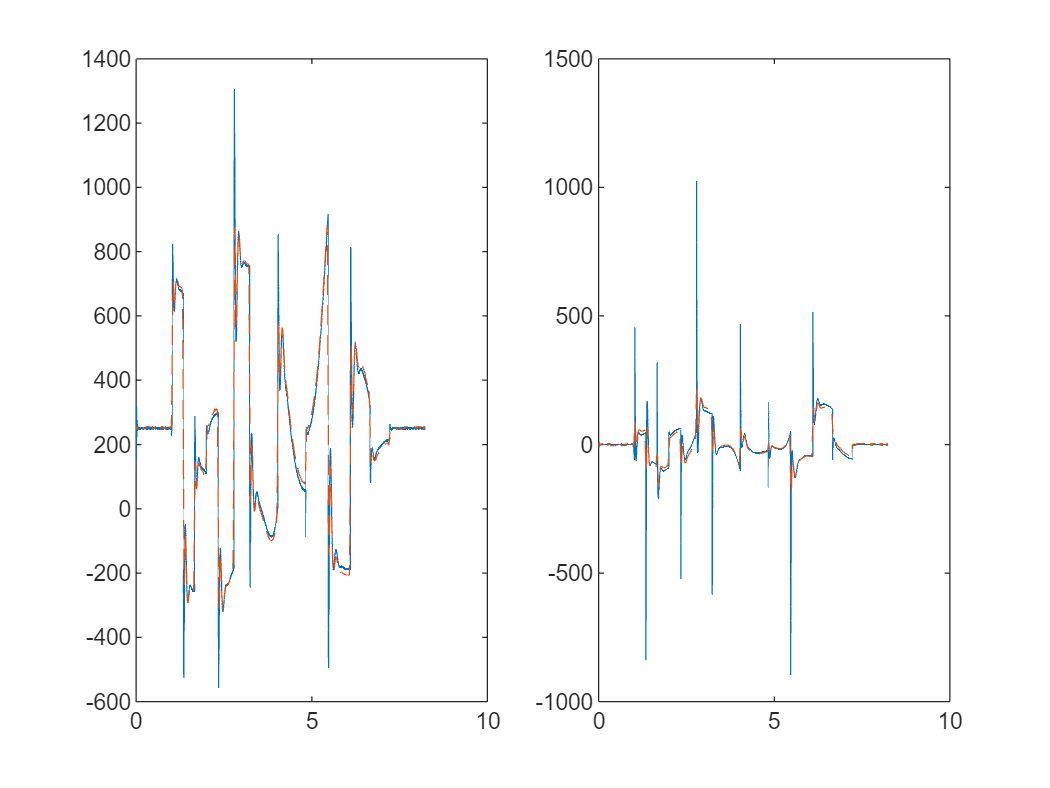

tau_model=FullRegressor*dynamic_parameters;
tau_model=reshape(tau_model,2,ndata)';
figure
subplot(1,2,1)
plot(test_data.time,test_data.joint_torque(:,1))
hold on

plot(test_data.time,tau_model(:,1),'--')

subplot(1,2,2)
plot(test_data.time,test_data.joint_torque(:,2))
hold on
plot(test_data.time,tau_model(:,2),'--')
